Настройки

cd '/home/viktor/ВАЖНО/Университет/Магистратура/Диплом_магистр'% путь к папке со скриптом и графиками. должен лежать файл F2_a
%название переменной
bb0=1; % 0 - выключено, 1 - включено и раскоменнтировать 2 строчки ниже
bb1=U1.time;  % x
bb2=U1.signals.values;   %y
%bb1=w.signals.values;  % x
%bb2=w.signals.values;   %y


naz='graf1'; %указать название файла
ram=0; %рамка 0 - выключено, 1 - включено
raz=[16 8]; %размер [ширина высота]
col='k';  %цвет графика 'k' - черный или [0 0 0]

%подпись осей
podpx='t,c';
podpy='U, B';  % для греческих символов нужно ставить \. Пример: \omega, рад/сек
                           % М, Н*м   t,c В*A*сек  U, B
%сетка
setka=1; %основная сетка 0 - выключено, 1 - включено
setkaD=1; %дополнительная сетка 0 - выключено, 1 - включено

%установка нуля
nol=0; %установка нуля в точных значениях
noll=[-0.02/2 -100/2];
nol_=0; %установка нуля через дробный коэф. (2,3,4 - оптимальный выбор)
noll_=[3 3];

%установка пределов
lim=0; % 0 - выключено, 1 - включено
limD=1;% доп отступ 0 - выключено, 1 - включено
xxLim=[0.1 0.18]; % пределы по оси X
yyLim=[-10 280];  % пределы по оси Y

очищаем workspase

%clear;

ввод данных

Ua=311;
f=50;
phi=0;
t=0:0.0001:0.1;
U=Ua*sin(2*pi*f*t+phi);
%a.Time=t;
%a.Data=U;
%xx=bb1;
%yy=bb2;
xx=t;
yy=U;

if bb0==1
    xx=bb1;
    yy=bb2;
end



график

f1=figure; %создаем фигуру
ax1=axes; %создаем координатную плоскость
p1=plot(ax1,xx,yy,'Color',col); %рисуем график

настройка графика

%ax=gca %текущая координатная плоскость
%настройка фигуры
f1.Color=[1 1 1]; %цвет подложки белый
f1.Units='centimeters'; %единицы размеров сантиметры
f1.Position=[0 0 raz(1) raz(2)]; %позиция графика
%настройка координатной плоскости
ax1.Units='centimeters'; %единицы размеров сантиметры
ax1.Position=[0.0 0.0 raz(1)-0.2 raz(2)-0.2];%позиция координатной плоскости



h1=gca;

%настройка шрифта 
h1.FontName='Times New Roman'; %имя шрифта
h1.FontSize=14; %размер шрифта
h1.LabelFontSizeMultiplier=1; %коэф. шрифта подписей 
h1.TitleFontSizeMultiplier=1;

%настройка сетки 
if setka==1
h1.XGrid='on'; %включить сетку по оси Х
h1.YGrid='on'; %включить сетку по оси Х
end

h1.GridColor=[0 0 0]; %цвет сетки

if setkaD==1
h1.XMinorGrid='on'; %включить промежуточную сетку по оси Х
h1.YMinorGrid='on'; %включить промежуточную сетку по оси Х
end

h1.GridAlpha=0.4; %прозрачность основной сетки
h1.MinorGridLineStyle='-'; %стиль промежуточной сетки "-" сплошная ":" точками
h1.MinorGridAlpha=0.2; %прозрачность промежуточной сетки

%настройка меток 
h1.TickDir='both'; %тип меток "both" слева и справа от оси
h1.XMinorTick='on'; %по оси X
h1.YMinorTick='on'; %по оси Y

%настройка положения 
h1.XAxisLocation='origin'; %положение подписи "origin" рядом с осью или сверху/снизу
h1.YAxisLocation='origin'; %положение подписи "origin" рядом с осью или слева/справа

%настройка цвета 
h1.XColor=[0 0 0]; %цвет оси X черный
h1.YColor=[0 0 0]; %цвет оси Y черный

h1.MinorGridColor=[0 0 0]; %цвет сетки

if lim==1
h1.XLim=xxLim;
h1.YLim=yyLim;
end

% {
%подгон размера
%h1.XTickMode='manual'
xt=get(h1,'XTick'); %считывание текущий меток
[xt Bx Dx Dx0 px]=F2_a(xt); %переопределение меток

if limD==1 
h1.XLim=Bx; %изменение пределов [min, max] по оси X
else
Bx=h1.XLim;
end


%h1.YTickMode='manual';
yt=get(h1,'YTick'); %считывание текущий меток
[yt By Dy Dy0 py]=F2_a(yt); %переопределение меток

if limD==1 
h1.YLim=By; %изменение пределов [min, max] по оси Y
else
By=h1.YLim;
end

%}

%h1.Position=[1 1 Dx+1 Dy+1];
%set(gca,'XTick',xt);
%set(gca,'YTick',yt);

%вставка стрелочек
[axxg ayyg]=dsxy2figxy(Bx,[0 0]);
[axxv ayyv]=dsxy2figxy([0 0],By);

annotation(f1,'arrow',axxg,ayyg,'LineWidth',0.7,'HeadWidth',7,'HeadLength',15);
annotation(f1,'arrow',axxv,ayyv,'LineWidth',0.7,'HeadWidth',7,'HeadLength',15);

%удаление рамки
if ram==0
[axx1 ayy1]=dsxy2figxy(Bx,[By(1) By(1)]);
[axx2 ayy2]=dsxy2figxy(Bx,[By(2) By(2)]);
[axx3 ayy3]=dsxy2figxy([Bx(1) Bx(1)],By);
[axx4 ayy4]=dsxy2figxy([Bx(2) Bx(2)],By);
annotation(f1,'line',axx1,ayy1,'LineWidth',2,'Color',[1 1 1]);
annotation(f1,'line',axx2,ayy2,'LineWidth',2,'Color',[1 1 1]);
annotation(f1,'line',axx3,ayy3,'LineWidth',2,'Color',[1 1 1]);
annotation(f1,'line',axx4,ayy4,'LineWidth',2,'Color',[1 1 1]);
end

%вставка подписей
    %podpx='\omegat';
   %podpy='\phi';
%podpy='U, В';
h1.XLabel.String=podpx;
h1.YLabel.String=podpy;



%замена точки на запятую
t1=get(h1,'YTickLabel');
t2=strrep(t1,'.',',');
set(h1,'YTickLabel',t2);

t3=get(h1,'XTickLabel');
t4=strrep(t3,'.',',');
set(h1,'XTickLabel',t4);


%установка нуля
n0=px/4;
n1=py/4;
if nol==1
    n0=noll(1);
    n1=noll(2);
end

if nol_==1
    n0=px/noll_(1);
    n1=py/noll_(2);
end

text(n0,n1,'0','FontSize',14,'FontName','Times New Roman') % px/2,py/2 ИЛИ px/4,py/4


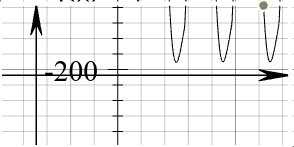

%сохранение
f1.PaperUnits='centimeters';
print(naz,'-dpng');